# Module 6: Control Flows II -- Conditional Statements

Conditional statements in MATLAB can help your code to respond dynamically to different situations. They enable you to create logic that can execute different code blocks based on specific conditions.

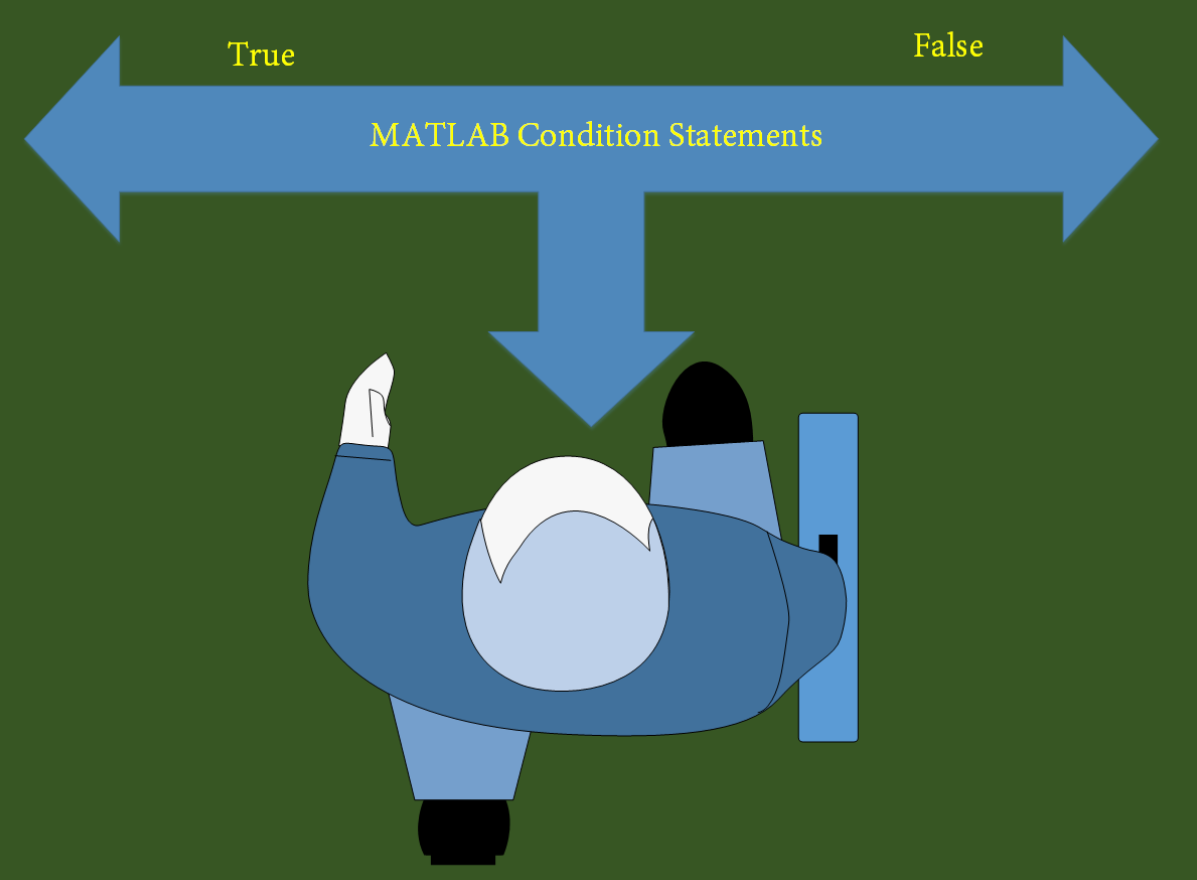

(source: [https://electricalworkbook.com/conditional-statements/](https://electricalworkbook.com/conditional-statements/) )

## 1. [Logical](https://www.mathworks.com/help/matlab/ref/logical.html?searchHighlight=logical&s_tid=srchtitle_support_results_1_logical) Datatype and Operations

### 1.1 The convertion between logical and numeric

logical is one basic datatype in Matlab, in addition to numeric

class(true)

ans = 'logical'

class(false)

ans = 'logical'

% for numerical operations (such as "+" here), true is viewed as 1 and false is 0 (from logical to numeric)
true + true  

ans = 2

sum([true true false]) % total number of true elements (1+1+0=2)

ans = 2

% convert numeric to logical: 0 i elements false and non-zeront is true (false, true, true)
logical([0 1 2]) 

ans = 1×3 logical array
   0   1   1


### 1.2 Basic operations/functions for logical variables

[](https://www.mathworks.com/help/matlab/ref/and.html#bu44441-A)[A & B](https://www.mathworks.com/help/matlab/ref/and.html)`:` An element of the output is set to logical `1` (`true`) if both `A` and `B` contain a nonzero element at that same location. Otherwise, the element is set to `0`.

true & true  % and 

ans = logical
   1


[](https://www.mathworks.com/help/matlab/ref/not.html#bu3um2z-A)[~A](https://www.mathworks.com/help/matlab/ref/not.html) : The output contains logical `1` (`true`) values where `A` is zero and logical `0` (`false`) values where `A` is nonzero.

~true  % not

ans = logical
   0


[](https://www.mathworks.com/help/matlab/ref/or.html?searchHighlight=true%20%7C%20false&s_tid=srchtitle_support_results_5_true%20%257C%20false#bu445ng-A)[A | B](https://www.mathworks.com/help/matlab/ref/or.html?searchHighlight=true%20%7C%20false&s_tid=srchtitle_support_results_5_true%20%257C%20false)`: `An element of the output is set to logical `1` (`true`) if either `A` or `B` contain a nonzero element at that same location. Otherwise, the element is set to `0`.

true | false % or

ans = logical
   1


0 | 1 % won't feel surprise now

ans = logical
   1


If `A` is a vector, then `B = `[any](https://www.mathworks.com/help/matlab/ref/any.html?s_tid=doc_ta)`(A)` returns logical `1` (`true`) if any of the elements of `A` is a nonzero number or is logical `1`, and returns logical `0` (`false`) if all the elements are zero.

any([true false false])

ans = logical
   1


If `A` is a vector, then [all](https://www.mathworks.com/help/matlab/ref/all.html?s_tid=doc_ta)`(A)` returns logical `1` (`true`) if all the elements are nonzero and returns logical `0` (`false`) if one or more elements are zero.

all([true false])

ans = logical
   0


Recall the relational operators for numeric arrays can also create logical arrays. 

v = [1 2 3 1];
sum(v==1) % use "==" to determine if the element is equal to 1 (for every element)

ans = 2

sum(v~=1) % use "~=" to determine if the element is NOT equal to 1 (for every element)

ans = 2

% step 1: use "~=" to determine if the element is NOT equal to 1 (for every element)
% step 2: use "v()" to select the elements that are NOT equal to 1
% step 3: calculate their sum
sum(v(v~=1)) 

ans = 5

v(v>=2)

ans =      2     3


any(v>2)

ans = logical
   1


all(v<4)

ans = logical
   1


## 2. The If Statement

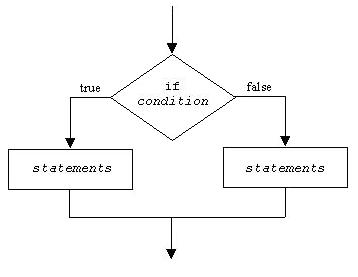

(source: [https://pages.cs.wisc.edu/~cs310-1/modules/Programming/_NOT%20USED%20MATLAB%20Programming/Conditional%20Execution/TopicDiscussion.html](https://pages.cs.wisc.edu/~cs310-1/modules/Programming/_NOT%20USED%20MATLAB%20Programming/Conditional%20Execution/TopicDiscussion.html) )

***Example 1: The simplest structure (one condition, one statement)***

x = rand % random number from 0 to 1

x = 0.5028

if x>0.5
    disp("x is greater than 0.5")
end

x is greater than 0.5


***Example 2: Two situations***

x = rand;
if x>0.5
    y = 1
else
    y = 0
end

***Example 3: For multiple conditions, using "***`elseif"`

x = randn % normal
if x > 0   % condition 1
    disp('positive')
elseif x<0 % condition 2
    disp('negative')
else  % all the remaining case
    disp('zero')
end

***Example 4: use logical operators in the condition***

Logical operations for various statements: it's recommended to use double signs ([short-circuit logical operations](https://www.mathworks.com/help/matlab/ref/logicaloperatorsshortcircuit.html)) &&(and) ||(or) for the efficiency of code.

x = 0;
if x > 0 || x<0  % or, note the double || here, you can also use the single |, but double is recommended
    disp('non-zero')
else  % all the remaining case
    disp('zero')
end

x = 4;
if x ~= 0  % not equal to
    disp('non-zero')
else  %all the remaining case
    disp('zero')
end

### ***In-class Exercise 1*** 

Define the function `isodd(n)` whose input is the positive integer n, and return true if n is odd and false if n is even. 

***Hint:**** use the *[mod](https://www.mathworks.com/help/matlab/ref/mod.html?s_tid=doc_ta)* function to find the remainder of division.*

isodd(2)

False


isodd(3)

Ture


### ***In-class Exercise 2*** 

Define the function `mydivisors(n) `whose input is the positive integer n, and return the row vector containing all the positive divisors of n. 

***Hint:**** combining the loop and if statement.*

mydivisors(10)

ans =      1     2     5    10


mydivisors(23)

ans =      1    23


## 3. The Switch Statement

A convenient replacement for multiple elseif conditions.

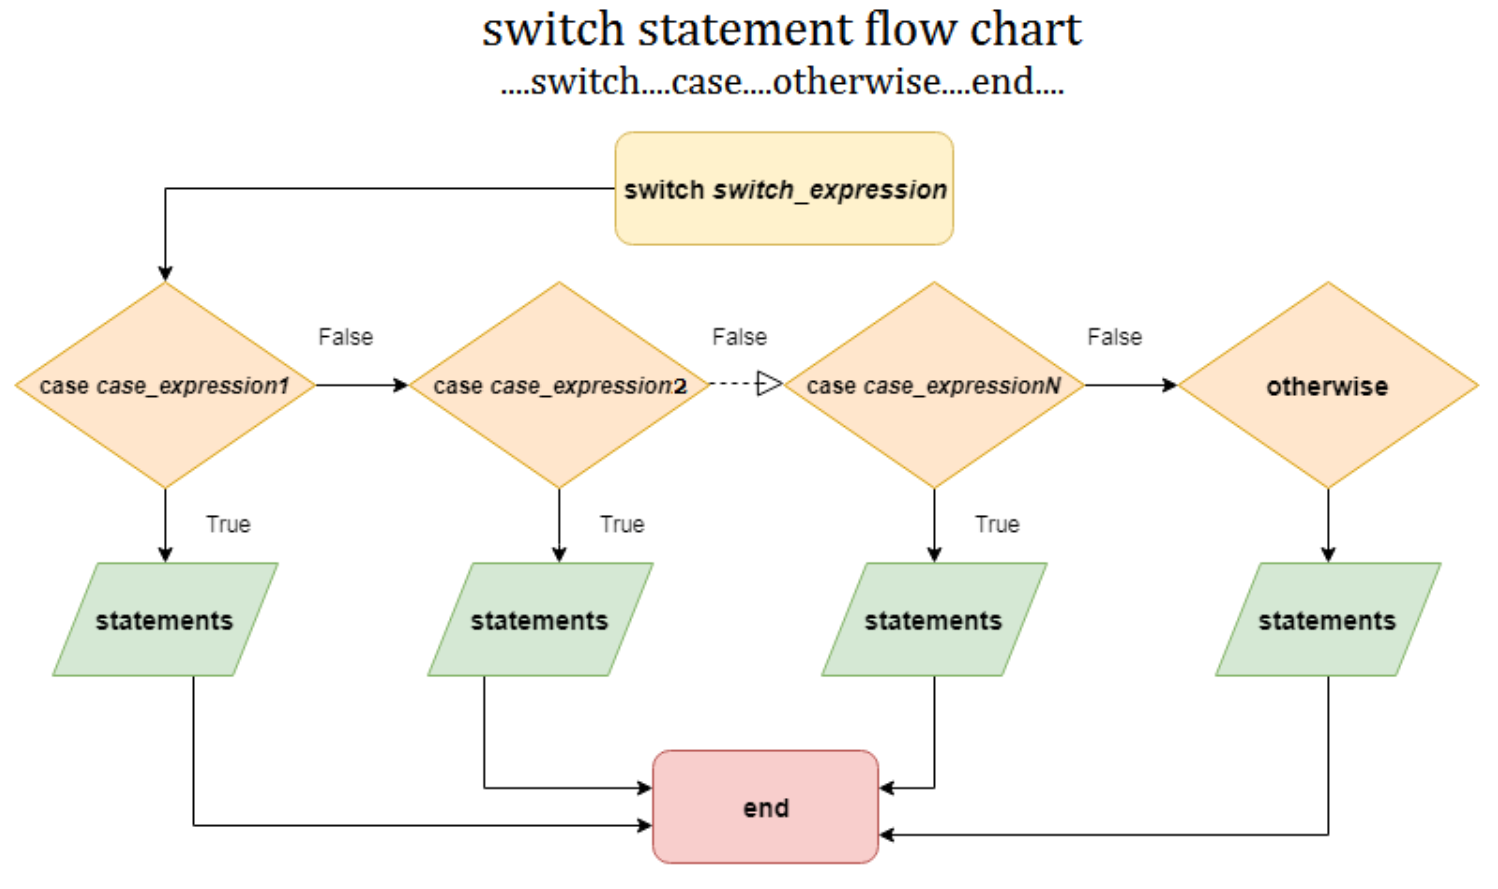

(source: https://www.javatpoint.com/matlab-switch)

n = 1;
switch n
    case -1
        disp('negative one')
    case 0
        disp('zero')
    case 1
        disp('positive one')
    otherwise  % all the remaining cases
        disp('other value')
end

### ***In-class Exercise 3*** 

Define the function `myintegral(f,a,b,n,formula)`, where formula is the input character 'left'  'right' 'midpoint', indicuating the numerical integral formula to use.

And test the following command:

myintegral(@sin,0,pi/2,100,'midpoint')

ans = 1.0000

myintegral(@sin,0,pi/2,100,'LEFT')

Not a valid method!


**Remark**: here the convenient way is to use switch statements. To use if statement, you should use [strcmp](https://www.mathworks.com/help/matlab/ref/strcmp.html?s_tid=doc_ta) function to compare the equivalence of characters (not ===).

myintegral(@(x)exp(-x.^4),0,2*pi,200,'midpoint')

ans = 0.9064

## 4. Other useful links

**Christopher Davis**’s videos about MATLAB: [https://www.youtube.com/playlist?list=PLHfGN68wSbbJvwG7QLXH3LXOTYBdBa3lr](https://www.youtube.com/playlist?list=PLHfGN68wSbbJvwG7QLXH3LXOTYBdBa3lr) 

**Yasmeen Baki**’s videos about MATLAB: [https://youtube.com/playlist?list=PL6ue_xaI6w4Nx3Cl0gqQS8XRVwMGi0M3w](https://youtube.com/playlist?list=PL6ue_xaI6w4Nx3Cl0gqQS8XRVwMGi0M3w)

## 5. **Functions defined in this livescript**

function x = isodd(n) % In-class Exercise 1
     if mod(n,2)==1
         disp('Ture')
     else
         disp('False')
     end
end


function x = mydivisors(n) % In-class Exercise 2
     v = [];
     for k = 1:ceil(n/2)
         if mod(n,k)==0
             v = [v k];
         end
     end
x = [v n];
end


function value = myintegral(f,a,b,n,formula) % In-class Exercise 3 
h = (b-a)/n;
x = a:h:b;
 switch formula
     case 'left'
         y = f(x);
         value = h*sum(y(1:end-1));
     case 'right'
         y = f(x);
         value = h*sum(y(2:end));
     case 'midpoint'
         x1 = x(1:1:n);
         x2 = x(2:1:(n+1));
         mid_point = ( x1 + x2 )/2;
         y = f(mid_point);
         value = h*sum(y(1:end));
     otherwise  % all the remaining cases
        disp('Not a valid method!')
 end
end